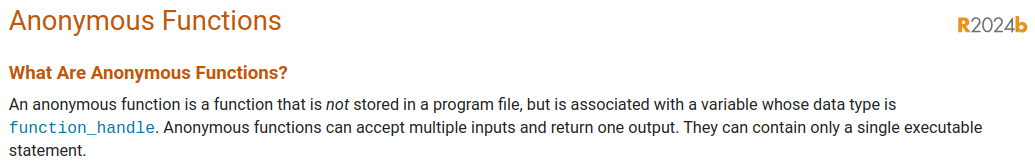

## Why?

- Used to parameterize functions we pass to MATLAB solvers (ode45, fminsearch, etc.).   This allows a wider variety of design implementations.  We can programmatically vary the constants/coefficients in the models.

- Can be used as a more succinct way to specify a handle to a simple function, as an alternative to defining a local function or creating a separate file with a standard function.   You will see this in the MATLAB documentation examples and or what gen AI provides.

## Example: Multidisciplinary Optimization of Ship Shafting

**Problem**: Design (choose "best" parameters) to minimize wear, vibration and whirling of propulsion shaft design.

**Model:**

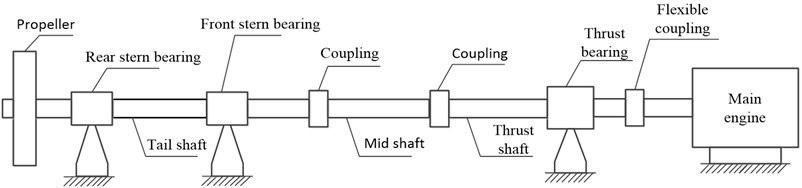

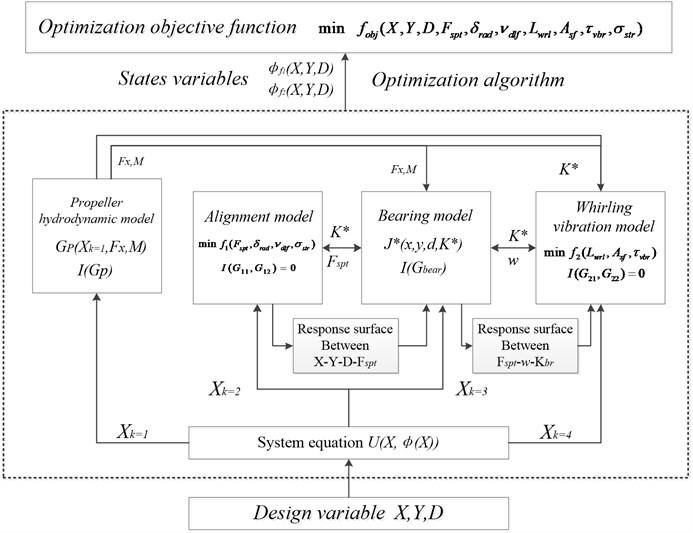

**Parameter Search:**

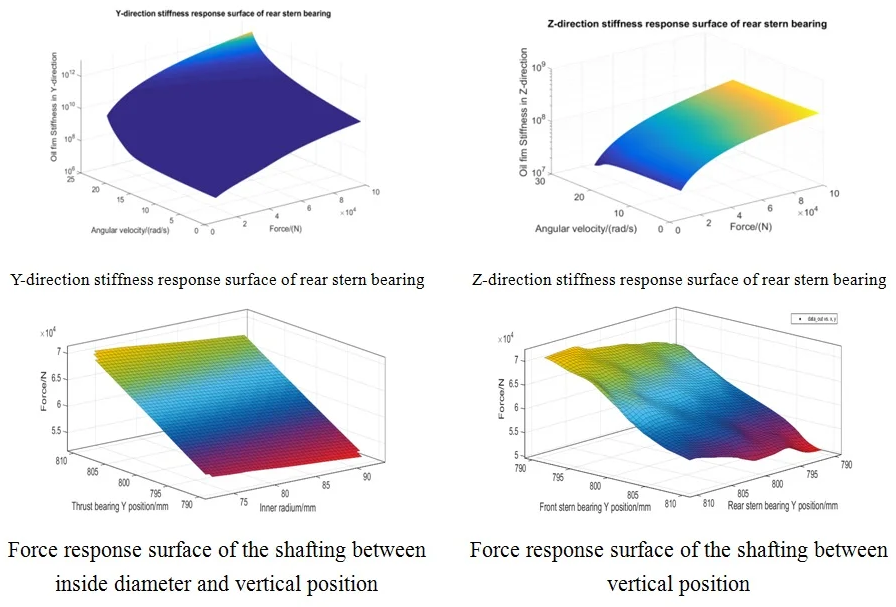

**Challenge: ** 

- How can we solve the model (a set of diff. eqs) for a variety of potential designs (model parameters)?

**Anonymous functions allow us to pass model parameters into the problem formulation to simulate many possible designs and optimize the results.**

## Syntax: [Anonymous Function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

The syntax is dense:

Some things to keep in mind about creating anonymous functions:

- The result is to create a new variable, HANDLE, of data type [function_handle](https://www.mathworks.com/help/matlab/ref/function_handle.html).

- This new function has input arguments specified as (ARG1, ARG2, ..., ARGN) 

- The EXPRESSION is a single executable statement

- The default behavior is that the anonymous funciton will return one output.

For example

hypotenuse_handle = @(a, b) sqrt(a^2 + b^2)

We can use the function handle as we've seen before

h = hypotenuse_handle(3,4)

### Using anonymous function as a rate function with ODE solvers

Instead of using a separate function as the rate function, we could use an anonymous function.  For example,

Consider a simple model of a speed control of a vessel

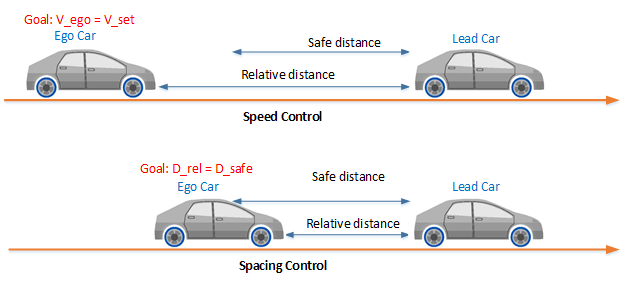


$$m\frac{dv(t)}{dt} + b \, v^2(t) = F_\text{engine}$$


with constants

- Vessel mass: $m=1000 \, \text{kg} $

- Drag coefficient: $b = 50 \, \text{N}/(\text{m/s}^2)$

- Engine thrust $F_{\text{engine}} = 2000 \, \text{N}$

We can write the rate function model as


$$\dot{v} = 1/m(-b \, v^2 + F_{\text{engine}})$$


which we can implement as

rfh = @(t,v) 1/1000 * (-50*v^2+2000)

Then we can pass this new function handle to the ODE solver

[tt, vv] = ode45(rfh, [0 20], 0);

plot(tt,vv)
grid("on")
xlabel("Time [s]")
ylabel("Speed [m/s]")

### Using variables in the EXPRESSION.

Unlike a separate expression (which has its own local scope), an anonymous function has access to the variables in the workspace.  For example, consider a quadratic function where the coefficients, a, b, c, are specified outside the function.


$$y = a x^2 + bx +c$$


a = 1;
b = 1;
c = 1;
quadratic_handle = @(x) a*x.^2 + b*x +c;
q = quadratic_handle(1)

What will happen if we re-define a constant and then call the anonymous function?

a = 2;
q2 = quadratic_handle(1)

What if we also redefine the anonymous function?

a = 2;
quadratic_handle = @(x) a*x.^2 + b*x +c;
q3 = quadratic_handle(1)

Which allows us to programmatically modify the constants 

figure;
xx = linspace(0,10,100);
a = 1;
c = 2;
for b = 1:5
    % Redefine our function with the new constants.
    quadratic_handle = @(x) a*x.^2 + b*x +c;
    % Call the function
    plot(xx, quadratic_handle(xx))
    hold on
end
hold off
xlabel("X [n/a]")
ylabel("Quadratic handle [n/a]")

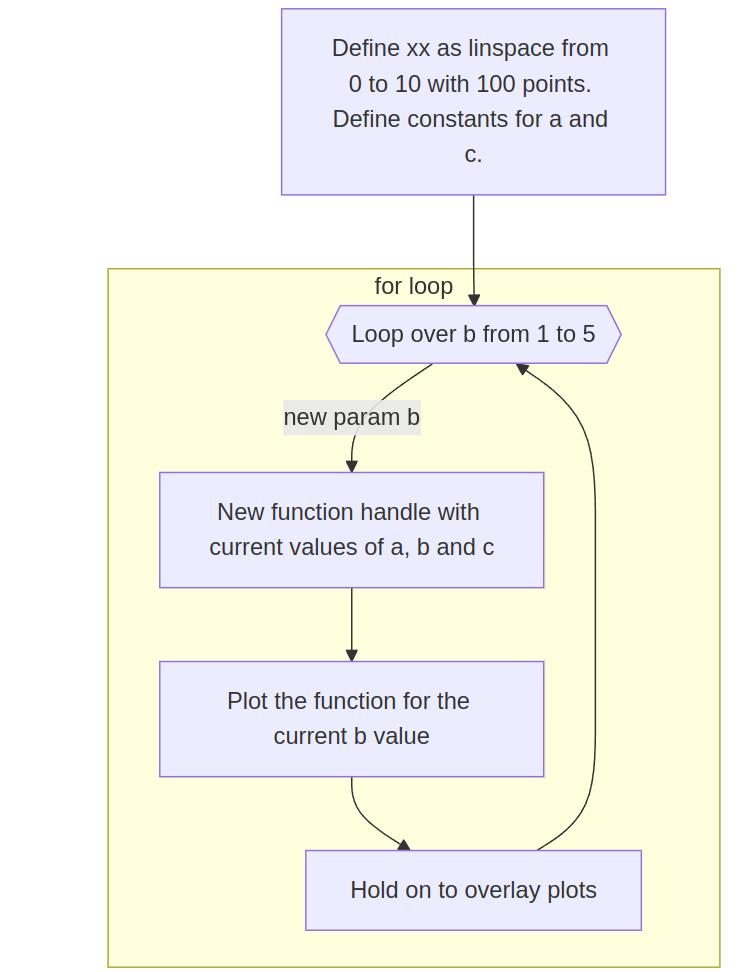

## Use-Case: Passing a parameterized anonymous function to a solver

We can put these two ideas together to parameterize the rate function so that we can vary the parameters of the model.

Consider an engineering design problem where we want to evaluate a few different designs, each with a different drag coefficient, and predict how varying the drag coefficient will affect the response.

**Problem:** Simulate the response of our vessel model for a range of values in the range $b = [40-60]\, \text{m/s}$.

We can solve this by using a loop to do the interation and creating a new function handle for each iteration.

clf;
bb = linspace(40, 60, 5);
for ii = 1:length(bb)
    % Assign parameters
    b = bb(ii);
    m = 1000;
    F = 2000;
    % Create new function handle with new parameters
    rfh = @(t,v) 1/m * (-b*v^2+F);
    % Simulate, AKA solve the ODE
    [tt, vv] = ode45(rfh, [0 20], 0);
    % Visualize
    plot(tt,vv,"DisplayName",sprintf("b = %.1f",b))
    hold on
end
legend("Location","southeast")
grid("on")
xlabel("Time [s]")
ylabel("Speed [m/s]")